**Исследование свойств множества Манедльброта 8^)**

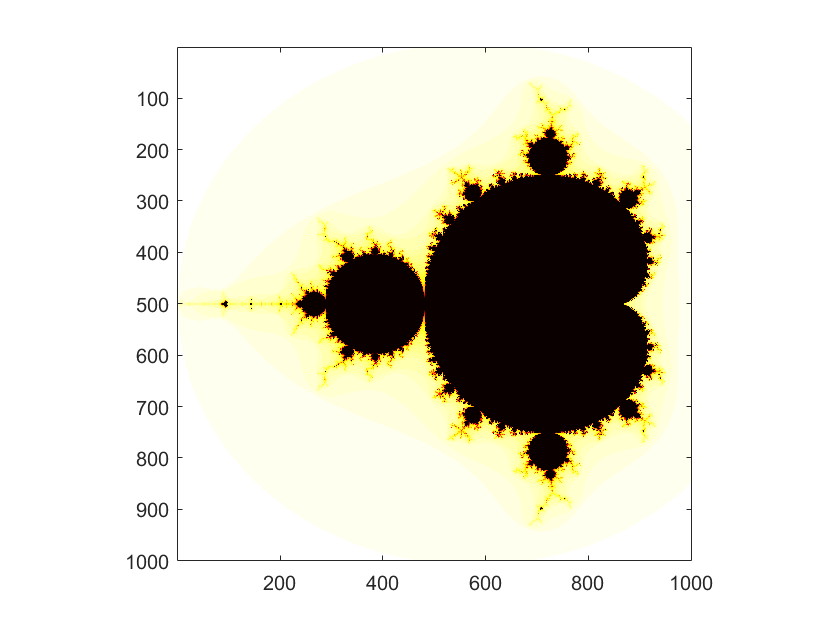

% Границы изменения "константы Мандельброта"
c_real_min = -2;    c_real_max = 0.6;
c_imag_min = -1.3;  c_imag_max = 1.3;

% количество точек (координат) построения 
n_crd = 1000;
% количество итераций
n_iter = 100;

[c_real, c_imag] = meshgrid(linspace(c_real_min, c_real_max, n_crd), linspace(c_imag_min, c_imag_max, n_crd));

c = c_real + 1i * c_imag;
z = zeros(size(c));
k = zeros(size(c));

for iter_idx = 1:n_iter
    z   = z.^2 + c;
    k(abs(z) > 2 & k == 0) = n_iter - iter_idx;
end

figure,
imagesc(k),
colormap hot
axis square